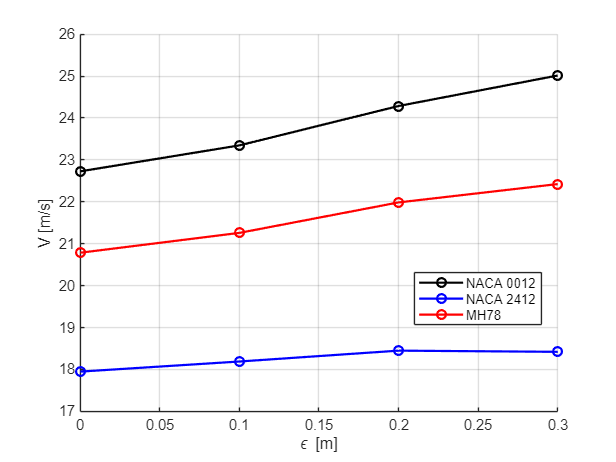

close all
clear
clc

load('multiple_sims_results.mat');

airfoils_vec = {"n0012", "naca2412", "mh78"};
root_vec = [0, 0.1, 0.2, 0.3];
twist_vec = [0, 5, 10, 15];
lambda_vec = [0.3 0.5 0.75, 1];

colors = {"k-o", "b-o", "r-o"};

% Pasta para salvar imagens
output_dir = 'figs/';
if ~exist(output_dir, 'dir')
    mkdir(output_dir)
end

% --------------------------
% Variação com root
% --------------------------

figure()
hold on, grid on
for ii = 1:length(airfoils_vec)
    plot(root_vec, squeeze(-v(ii, :, 1, 1)), colors{ii}, LineWidth=1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\epsilon [m]")
ylabel("V [m/s]")
exportgraphics(gcf, fullfile(output_dir, 'V_vs_root.png'))

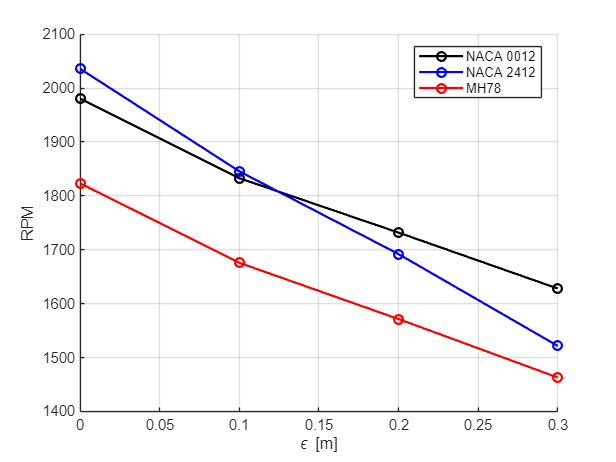


figure()
hold on, grid on
for ii = 1:length(airfoils_vec)
    plot(root_vec, squeeze(rpm(ii, :, 1, 1)) * 60 / (2*pi), colors{ii}, LineWidth=1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\epsilon [m]")
ylabel("RPM")
exportgraphics(gcf, fullfile(output_dir, 'RPM_vs_root.png'))

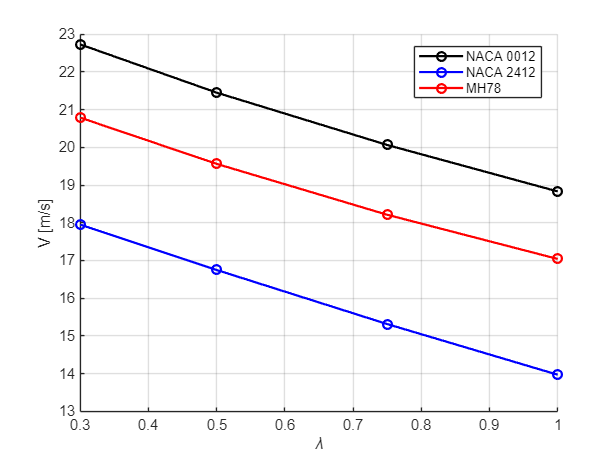


% --------------------------
% Variação com lambda
% --------------------------

figure()
hold on, grid on
for ii = 1:length(airfoils_vec)
    plot(lambda_vec, squeeze(-v(ii, 1, 1, :)), colors{ii}, LineWidth=1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\lambda")
ylabel("V [m/s]")
exportgraphics(gcf, fullfile(output_dir, 'V_vs_lambda.png'))

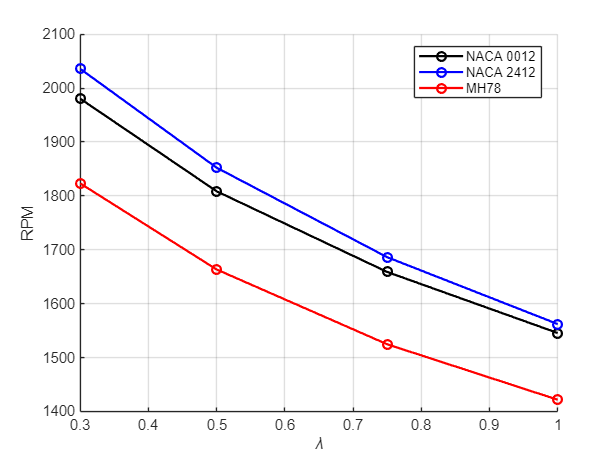


figure()
hold on, grid on
for ii = 1:length(airfoils_vec)
    plot(lambda_vec, squeeze(rpm(ii, 1, 1, :)) * 60 / (2*pi), colors{ii}, LineWidth=1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\lambda")
ylabel("RPM")
exportgraphics(gcf, fullfile(output_dir, 'RPM_vs_lambda.png'))

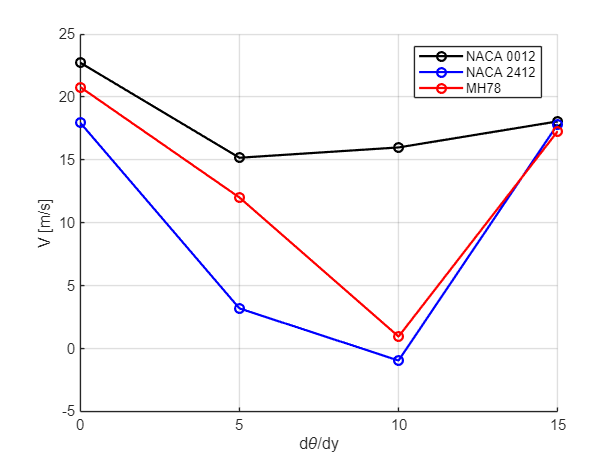


% --------------------------
% Variação com twist
% --------------------------

figure()
hold on, grid on
for ii = 1:length(airfoils_vec)
    plot(twist_vec, squeeze(-v(ii, 1, :, 1)), colors{ii}, LineWidth=1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("d\theta/dy")
ylabel("V [m/s]")
exportgraphics(gcf, fullfile(output_dir, 'V_vs_twist.png'))

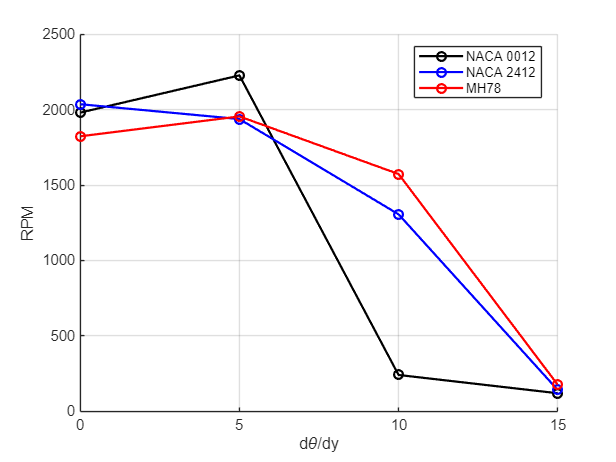


figure()
hold on, grid on
for ii = 1:length(airfoils_vec)
    plot(twist_vec, squeeze(rpm(ii, 1, :, 1)) * 60 / (2*pi), colors{ii}, LineWidth=1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("d\theta/dy")
ylabel("RPM")
exportgraphics(gcf, fullfile(output_dir, 'RPM_vs_twist.png'))